# Chapter 04: Support Vector Machines -- Kernel tricks only

close all; clear all; 
warning('off','all') % There is a warning when we use fcontour to draw a plot
% the warning shows if we comment this line. 

## First case of two classes clearly not linearly separable

The blue dots are still labeled negatively and the red crosses are still labeled positively

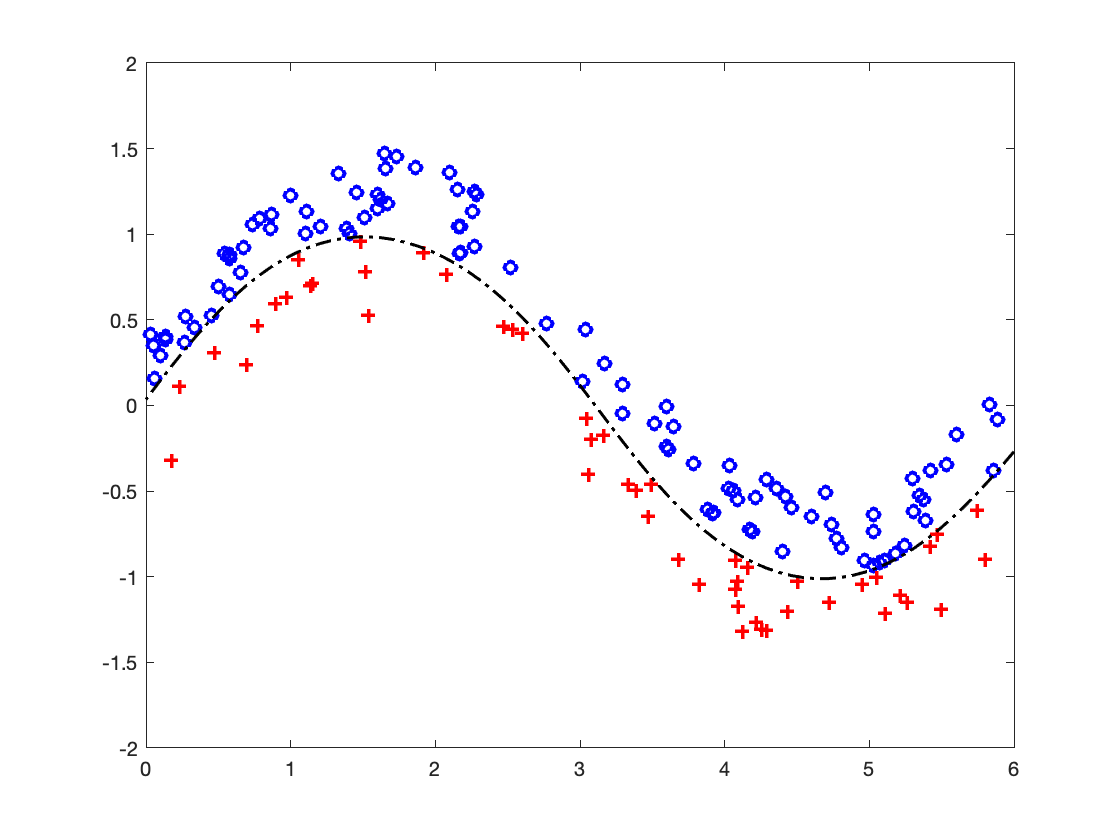

% generate the data
m0 = 100;
m1 = 50;
X0 = zeros(m0,2); 
X0(:,1) = 6*rand(m0,1);                          % abscissae of the blue dots
X0(:,2) = sin(X0(:,1)) + 0.5*rand(m0,1);         % their ordinates
X1 = zeros(m1,2);
X1(:,1) = 6*rand(m1,1);                          % abscissae of the red crosses
X1(:,2) = sin(X1(:,1)) - 0.5*rand(m1,1);         % their ordinates
figure(3)
plot(X0(:,1),X0(:,2),'bo',X1(:,1),X1(:,2),'r+','Linewidth',2)
hold on
% Soft SVM with a polynomial kernel
X = [X0; X1];
y = [-ones(m0,1); +ones(m1,1)];
K = (1 + X*X').^3;
lambda=1e-3;
[a_poly,b_poly] = kernel_svm(K,lambda,m0,m1);
% visualize the separating surface
f = @(u,v) a_poly'*(1+X*[u;v]).^3 - b_poly;
fcontour(f,[0,6,-2,2],'k-.','Linewidth',1.5,'LevelList',0)

## Second case of two classes clearly not linearly separable

blue dots labeled negatively, red crosses labeled positively

## generate the data

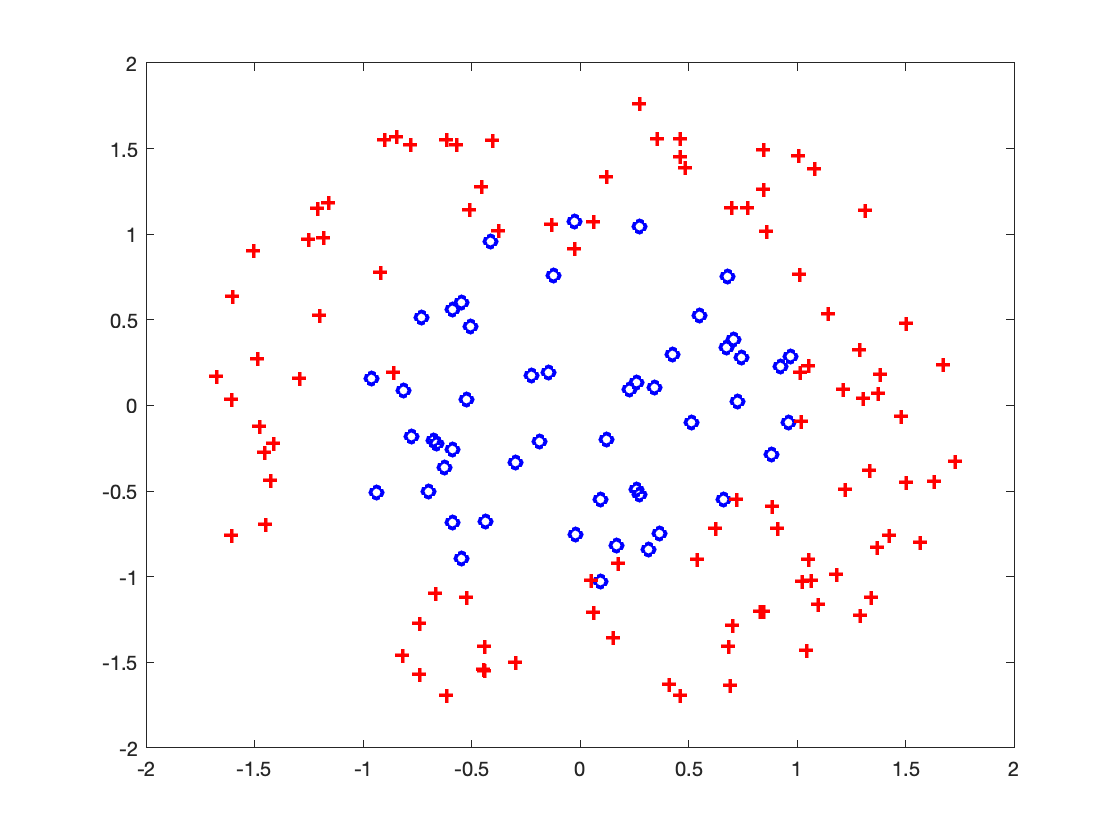

close all; clear all;
% generate the data
m0 = 50;
m1 = 100;
r0 = 1.1*sqrt(rand(m0,1));
theta0 = 2*pi*rand(m0,1);
r1 = 0.8+sqrt(rand(m1,1));
theta1 = 2*pi*rand(m1,1);
X = [r0.*cos(theta0), r0.*sin(theta0);...
     r1.*cos(theta1), r1.*sin(theta1)];
y = [-ones(m0,1); +ones(m1,1)];
figure(4)
plot(X(1:m0,1),X(1:m0,2),'bo',X(m0+1:end,1),X(m0+1:end,2),'r+','Linewidth',2)
hold on

## Soft SVM with a gaussian kernel

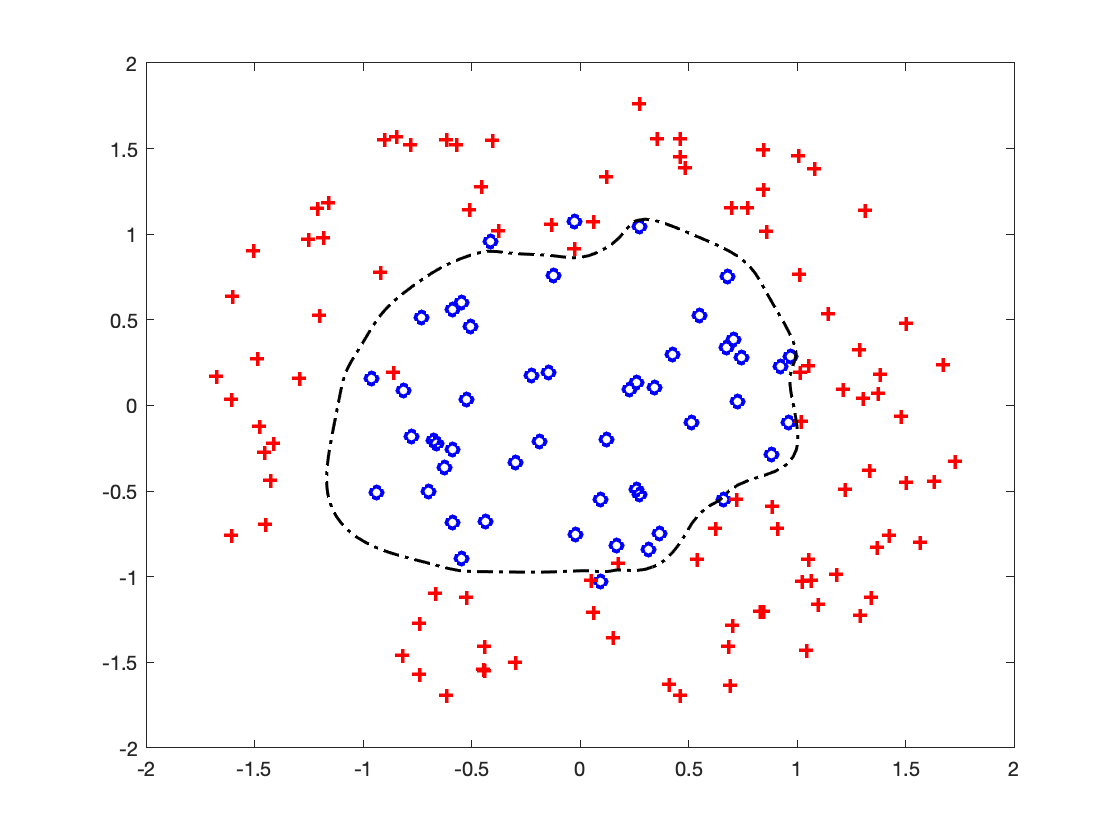

sigma = 1;
m = m0+m1;
K = zeros(m,m);
for i = 1:m
    for j = 1:m
    K(i,j) = exp(-norm(X(i,:)-X(j,:))/2/sigma^2);
    end
end
lambda=1e-1;
[a_expo,b_expo] = kernel_svm(K,lambda,m0,m1);
% visualize the separating surface
f = @(u,v) a_expo'*exp( -sqrt(diag(X*X') - 2*X*[u;v] + u^2+v^2)/2/sigma^2 )...
    - b_expo; 
fcontour(f,[-1.5,1.5,-1.5,1.5],'k-.','Linewidth',1.5,'LevelList',0)

function [a,b] = kernel_svm(K,lambda,m0,m1)
cvx_quiet true
cvx_begin
variable a(m0+m1)
variable b
variable xi(m0+m1) nonnegative
minimize ( a'*K*a + (1/lambda)*sum(xi) )
subject to
(K(1:m0,:)*a-b) <= -1+xi(1:m0) 
(K(m0+1:end,:)*a-b) >= 1-xi(m0+1:end) 
cvx_end
end